rng(1)
clearvars
[filename,path] = uigetfile('MultiSelect','on');

if ~iscell(filename)
    filename = {filename};
end

for i=1:length(filename)
    
    S = load([path,filename{i}]);
    fieldname = fieldnames(S);
    struct_cell = S.(fieldname{1});
    
    rng(1)
    split_filename = split(filename{i},'_');
    %Date of experiment
    experiment_date = split_filename{1};
    
    %Sensor used
    sensor = 'nes';
    
    %Does it bind zinc? Or is it dead?
    %(You can also put any other info here,
    %like knockdowns or other cell-type specific identifiers)
    
    colors_cell = {'#33637a','#3DA5D9','#0C0808',...
        '#CE9600','#ED8A07','#B35C05'};
    cell_type = split_filename{2};
    
    
    condition_cell = {'MM'};
    conditions_to_plot = 1;
    media_change = 17;
    
    
    FRET_min = 3;
    FRET_max = 8;
    
    y_min = 3.5;
    y_max = 7;
    
    
end


c = conditions_to_plot;

mitosis_store = [];
yfp_store = [];
cfp_store = [];
dhb_store_nuc = [];
dhb_store_cyto = [];
for nd=1:numel(struct_cell)
    curr_struct = struct_cell{nd,c,1};
    
    if ~isempty(curr_struct)
        if ~isempty(curr_struct.dhb_nuc)
            dhb_store_nuc = [dhb_store_nuc;curr_struct.dhb_nuc];
            dhb_store_cyto = [dhb_store_cyto;curr_struct.dhb_cyto];
            cfp_store = [cfp_store;curr_struct.CFP];
            yfp_store = [yfp_store;curr_struct.YFP];
            mitosis_store = [mitosis_store;curr_struct.mitosis];
            
        end
    else
        continue
    end
end
num_frames = size(dhb_store_nuc,2);
curr_dhb = dhb_store_cyto./(dhb_store_nuc);
curr_fret = yfp_store./cfp_store;
dhb_smooth = movmean(curr_dhb, 5,2,'omitnan');
fret_smooth = movmean(curr_fret, 1,2,'omitnan');


imt = cellfun(@diff,mitosis_store,'UniformOutput',false);
imt_log = cellfun(@(x) x<50, imt, 'UniformOutput', false);
imt_filter = cell2mat(cellfun(@sum, imt_log, 'UniformOutput',false)) == 0;

divide_after_change = cell2mat(cellfun(@(x) sum(x<media_change)<1 | isempty(x),mitosis_store,'UniformOutput',false));

max_int_filter = max(dhb_smooth,[],2,'omitnan') < 2.5;
min_int_filter = min(dhb_store_nuc,[],2,'omitnan') > 100;


filter_vec_2 = max(curr_fret,[],2,'omitnan') < FRET_max ...
    & min(curr_fret,[],2,'omitnan') > FRET_min ...
    & min(cfp_store,[],2,'omitnan') > 100 ...
    & max(cfp_store,[],2,'omitnan') < Inf;

all_filter = max_int_filter & imt_filter & divide_after_change & min_int_filter & filter_vec_2;

dhb_all = dhb_smooth(all_filter,:);
fret_all = fret_smooth(all_filter,:);
mitosis_all = mitosis_store(all_filter,:);

rng(1)
[idx,clust,sumd] = kmedoids(dhb_all,4,'Distance',@dtwf);


figure
tiledlayout('flow')

title_cell = {{'Cluster 1', 'Semisynchronized'},...
    {'Cluster 2', 'CDK2 Low All Timelapse'},...
    {'Cluster 3','CDK2 High'},...
    {'Cluster 4', 'CDK2 Low to Dividing'},...
    {'All Tracks'}};

cluster_1 = sum(idx==1)/sum(~isnan(idx))

cluster_1 = 0.1825

cluster_2 = sum(idx==2)/sum(~isnan(idx))

cluster_2 = 0.1592

cluster_3 = sum(idx==3)/sum(~isnan(idx))

cluster_3 = 0.2809

cluster_4 = sum(idx==4)/sum(~isnan(idx))

cluster_4 = 0.3775

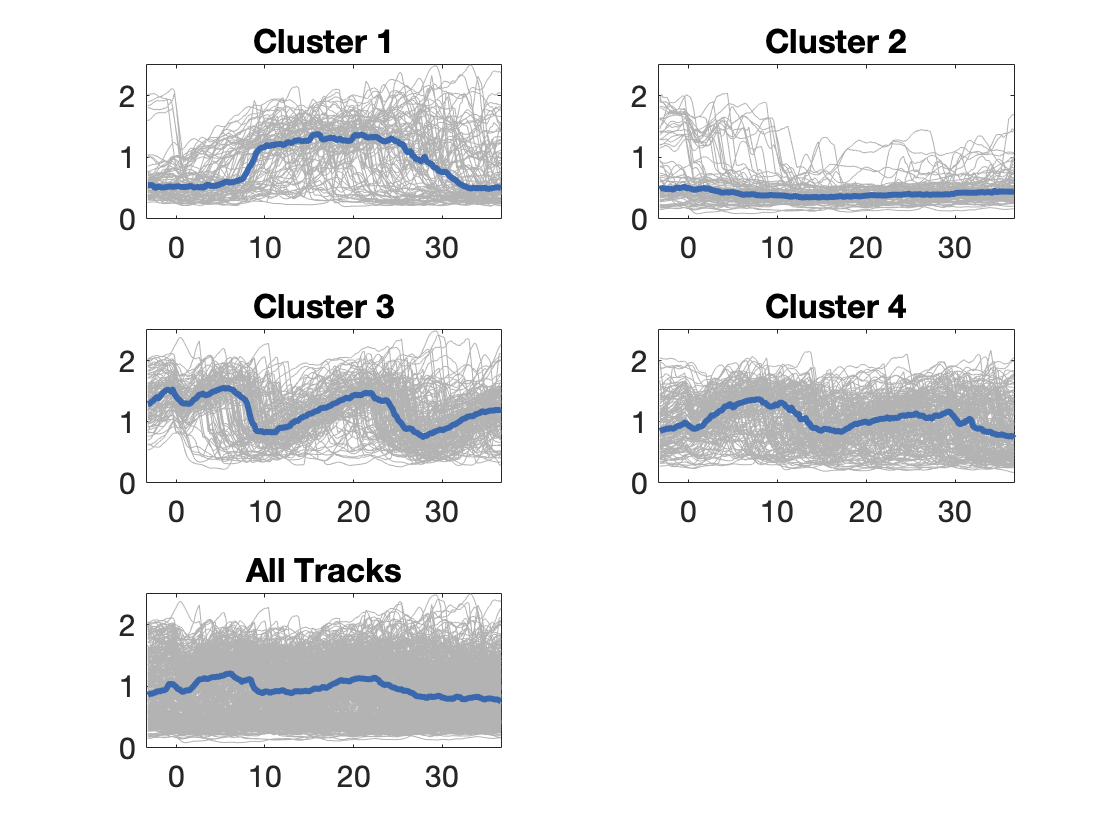

plot_vec = ((1:num_frames) - media_change)/5;
x_limits = [(-1*media_change)/5, (num_frames-media_change)/5];

for i=1:5
    
    if i < 5
        ax = nexttile;
        plot(plot_vec,dhb_all(idx==i,:),'LineWidth',0.25,'Color',[0.7,0.7,0.7])
        hold on
        plot(plot_vec, median(dhb_all(idx==i,:)),'LineWidth',3,'Color','#3A68AE')
        title(title_cell{i}(1))
        ylim([0,2.5])
        xlim(x_limits)
        ax.FontSize = 15;
        
    elseif i == 5
        ax = nexttile;
        ax.FontSize = 30;
        plot(plot_vec,dhb_all(~isnan(idx),:),'LineWidth',0.25,'Color',[0.7,0.7,0.7])
        hold on
        plot(plot_vec, median(dhb_all(~isnan(idx),:)),'LineWidth',3,'Color','#3A68AE')
        title(title_cell{5}(1))
        ylim([0,2.5])
        xlim(x_limits)
        ax.FontSize = 15;
        
    end
end

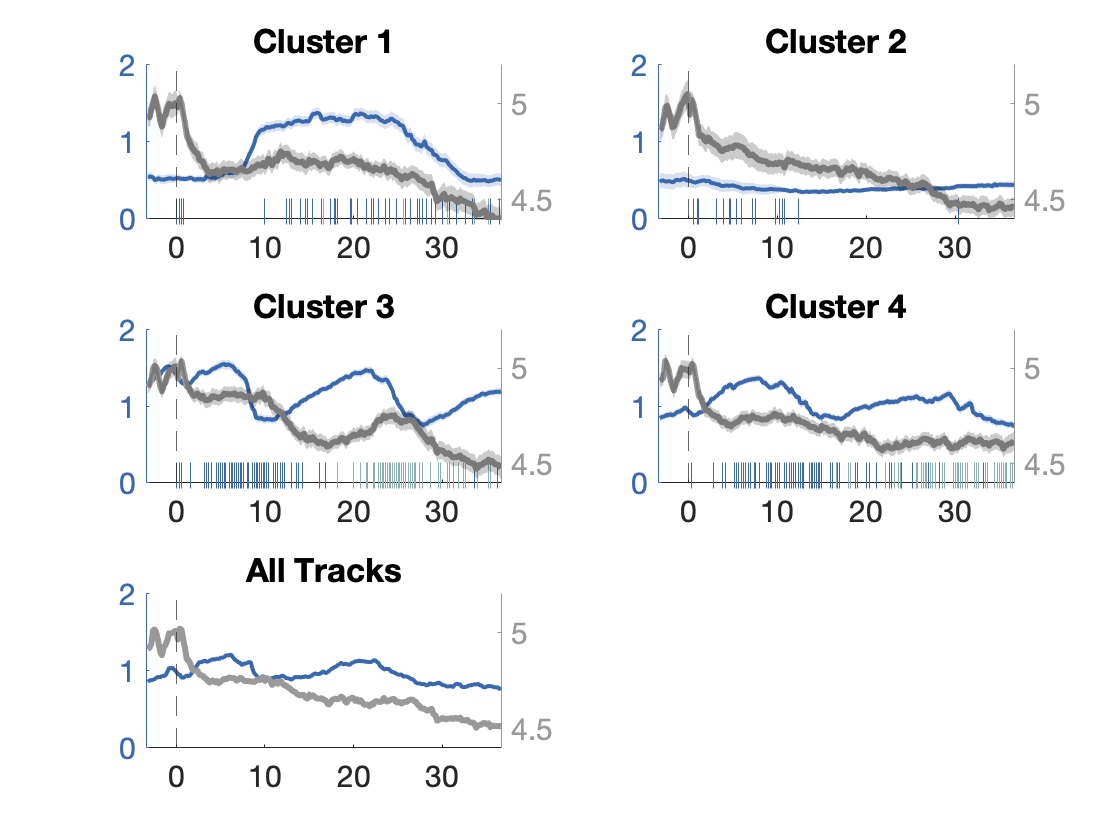

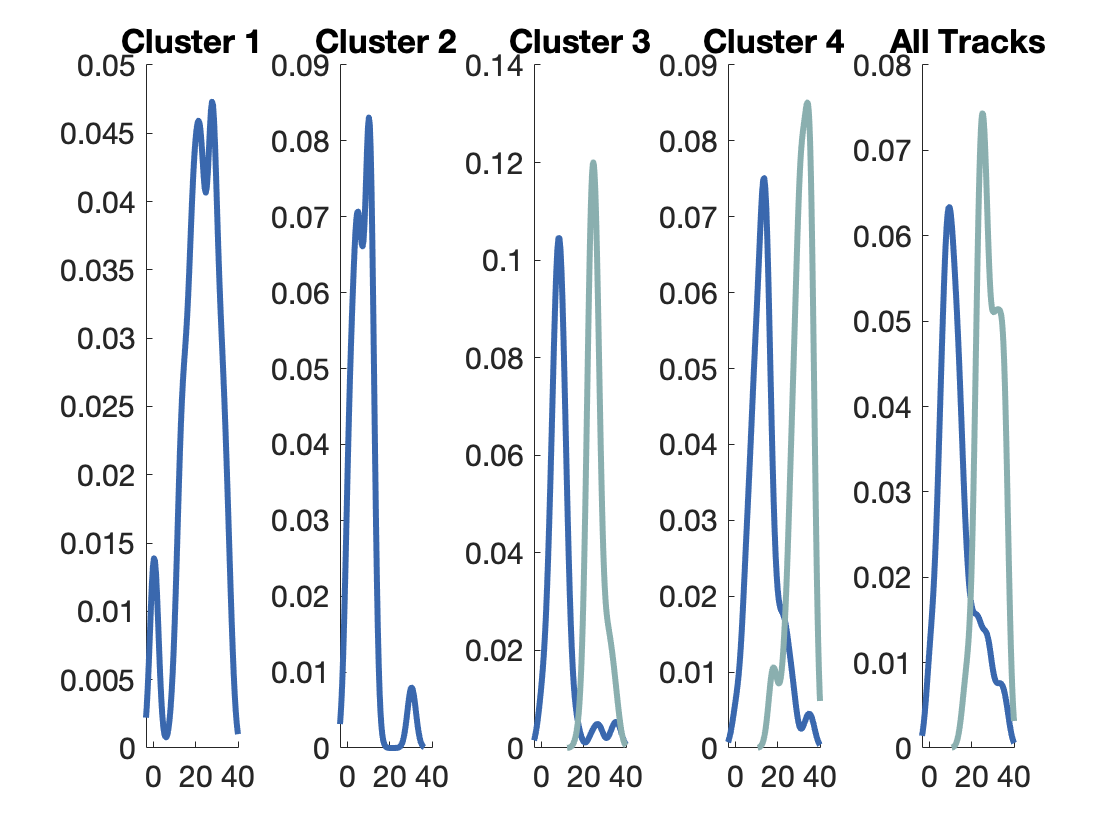

figure
t=tiledlayout('flow');
figure
t2=tiledlayout(1,5);
plot_frame = ((1:num_frames)-media_change)/5;


for j=1:5
    
    if j < 5
        ax = nexttile(t,j);
        box off
        
        fret_mean = mean(fret_all(idx==j,:),'omitnan');
        CI_zinc = get_ci(fret_all(idx==j,:), 0.95);
        CI_plot_zinc = CI_zinc + fret_mean;
        
        dhb_mean = median(dhb_all(idx==j,:),'omitnan');
        CI_dhb = get_ci(dhb_all(idx==j,:),0.95);
        CI_plot_dhb = CI_dhb + dhb_mean;
        
        colororder({'#3A68AE','#999999'})
        yyaxis left
        hold on
        plot(plot_frame, median(dhb_all(idx==j,:),'omitnan'),'-', "LineWidth",2, 'Color', '#3A68AE')
        hold on
        fill([plot_frame, fliplr(plot_frame)], [CI_plot_dhb(1,:),fliplr(CI_plot_dhb(2,:))],'-w', 'FaceAlpha',0.2, 'FaceColor','#3A68AE', 'EdgeAlpha', 0)

        ylim([0,2])
        yyaxis right
        plot(plot_frame,fret_mean,'-k','LineWidth',3, 'Color',[0.6,0.6,0.6])
        hold on
        fill([plot_frame, fliplr(plot_frame)], [CI_plot_zinc(1,:),fliplr(CI_plot_zinc(2,:))],'-k', 'FaceAlpha',0.2, 'EdgeAlpha', 0)

        
        ylim([4.4,5.2])
        title(title_cell{j}(1))
        xlim([-1*media_change/5, (200-media_change)/5])
        xline(0,'--')
        ax.FontSize=15;
        
        
        
        for i=1:2
            plot_mitosis = (unpack_mitosis(mitosis_all(idx==j,:),i)-media_change)/5;
            
            if numel(plot_mitosis) > 10
                
                try
                    [prob_curr, vector_curr] = ksdensity(plot_mitosis,[],"Bandwidth",2);
                catch
                    prob_curr = 0;
                    vector_curr = 0;
                end
            else
                prob_curr = 0;
                vector_curr = 0;
            end
            
            nexttile(t,j)
            yyaxis left
            hold on
            plot(plot_mitosis, zeros(numel(plot_mitosis),1) + 0.1,'|','Color',double((uint8([58, 104, 174])+80*i - 80))/255, 'MarkerSize',12)
            
            ax2=nexttile(t2,j);
            hold on
            box off
            plot(vector_curr, prob_curr,'LineWidth',3,'Color',double((uint8([58, 104, 174])+80*i - 80))/255)
            xlim([-1*media_change/5, (200-media_change)/5])
            title(title_cell{j}(1))
            xlim([-1*media_change/5,40])
            ax2.FontSize = 15;
        end
        
    elseif j==5
        ax=nexttile(t,j);
        box off
        colororder({'#3A68AE','#999999'})
        yyaxis left
        hold on
        plot(plot_frame, median(dhb_all(~isnan(idx),:),'omitnan'),'-', "LineWidth",2, 'Color', '#3A68AE')
        ylim([0,2])
        yyaxis right
        plot(plot_frame,mean(fret_all(~isnan(idx),:),'omitnan'),'-k','LineWidth',3, 'Color',[0.6,0.6,0.6])
        ylim([4.4,5.2])
        title(title_cell{j}(1))
        ax.FontSize=15;
        xlim([-1*media_change/5, (200-media_change)/5])
        xline(0,'--')
        
        for i=1:2
            plot_mitosis = (unpack_mitosis(mitosis_all(~isnan(idx),:),i)-media_change)/5;
            
            
            
            try
                [prob_curr, vector_curr] = ksdensity(plot_mitosis,[],"Bandwidth",2);
            catch
                prob_curr = 0;
                vector_curr = 0;
            end
            
            hold on
            
            ax2=nexttile(t2,j);
            box off
            plot(vector_curr, prob_curr,'LineWidth',3,'Color',double((uint8([58, 104, 174])+80*i - 80))/255)
            xlim([-1*media_change/5, (200-media_change)/5])
            title(title_cell{j})
            xlim([-1*media_change/5,40])
            ax2.FontSize=15;

        end
        
    end
end

figure
t=tiledlayout(1,5);


for j=1:4
    first_mit_store = [];
    second_mit_store = [];
    for track = 1:numel(mitosis_all(idx==j))
        
        quiescent_mitosis = mitosis_all(idx==j);
        quiescent_fret = fret_all(idx==j,:);
        %get the signals out from the "store" variables
        mitoses = quiescent_mitosis{track};
        FRET = quiescent_fret(track,:);
        
        if ~isempty(mitoses) && numel(quiescent_mitosis) > 10
            
            %if it divides, we can align it to mitosis
            for i=numel(mitoses)
                
                
                curr_mit = mitoses(i);
                
                
                %create a zero matrix that's double the number of
                %frames
                
                
                FRET_store_temp = nan(1,2*num_frames);
                
                
                %replace the indices in the FRET_store_temp vector that
                %correspond to the FRET aligned to mitosis with the
                %FRET values
                FRET_store_temp(num_frames-curr_mit:end-curr_mit-1)=FRET;
                if i == 1
                    first_mit_store = [first_mit_store;FRET_store_temp];
                elseif i == 2
                    second_mit_store = [second_mit_store;FRET_store_temp];
                end
                
                
            end
        end
    end
    ax=nexttile;
    
    plot((-1*num_frames:num_frames-1)/5, mean(first_mit_store,'omitnan'),'LineWidth',3)
    hold on
    plot((-1*num_frames:num_frames-1)/5, mean(second_mit_store,'omitnan'),'LineWidth',3)
    xline(0,'--','Mitosis')
    xlim([-4, 12])
    ylim([4.3,5.5])
    title(title_cell{j}(1))
    ax.FontSize=15;
    
end

first_mit_store = [];
second_mit_store = [];
for track = 1:numel(mitosis_all(~isnan(idx)))
    
    quiescent_mitosis = mitosis_all(~isnan(idx));
    quiescent_fret = fret_all(~isnan(idx),:);
    %get the signals out from the "store" variables
    mitoses = quiescent_mitosis{track};
    FRET = quiescent_fret(track,:);
    
    if ~isempty(mitoses)
        
        %if it divides, we can align it to mitosis
        for i=numel(mitoses)
            
            
            curr_mit = mitoses(i);
            
            
            %create a zero matrix that's double the number of
            %frames
            
            
            FRET_store_temp = nan(1,2*num_frames);
            
            
            %replace the indices in the FRET_store_temp vector that
            %correspond to the FRET aligned to mitosis with the
            %FRET values
            FRET_store_temp(num_frames-curr_mit:end-curr_mit-1)=FRET;
            if i == 1
                first_mit_store = [first_mit_store;FRET_store_temp];
            elseif i == 2
                second_mit_store = [second_mit_store;FRET_store_temp];
            end
            
            
        end
    end
end
ax = nexttile

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.7986 0.1100 0.1064 0.8123]
            Units: 'normalized'

  Show all properties


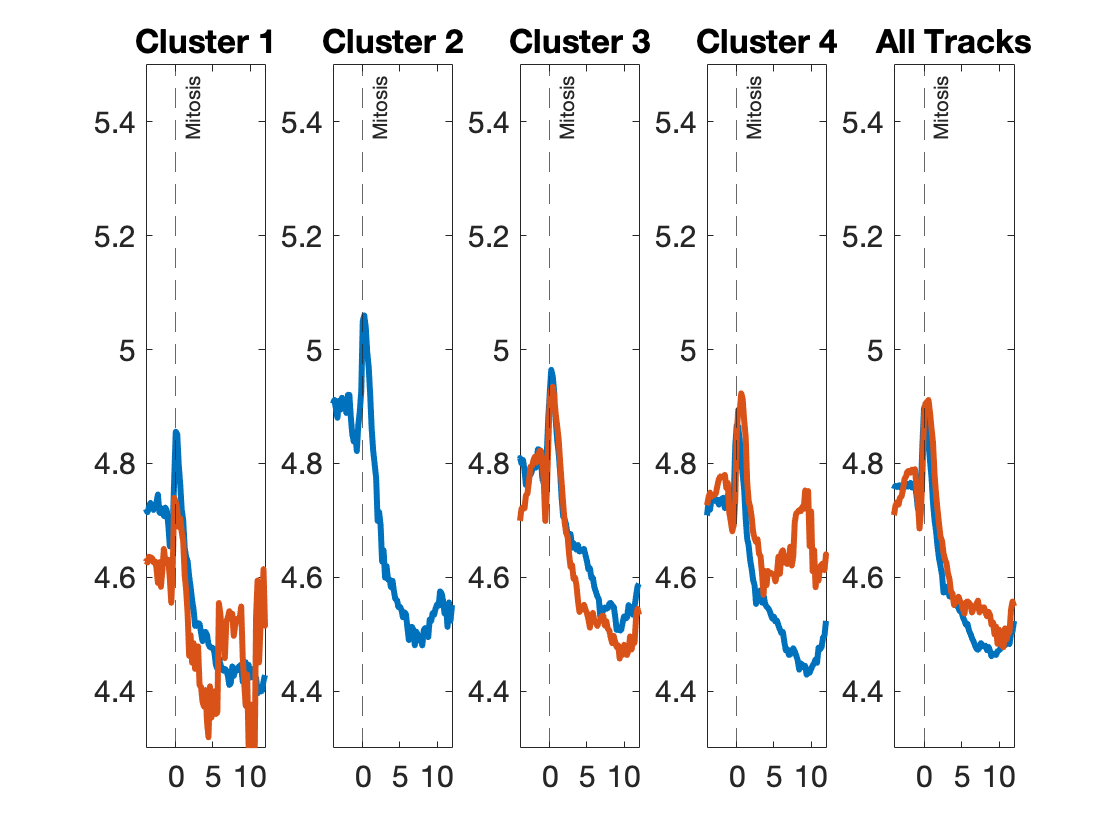

plot((-1*num_frames:num_frames-1)/5, mean(first_mit_store,'omitnan'),'LineWidth',3)
hold on
plot((-1*num_frames:num_frames-1)/5, mean(second_mit_store,'omitnan'),'LineWidth',3)
xline(0,'--','Mitosis')

xlim([-4, 12])
ylim([4.3,5.5])
title('All Tracks')
ax.FontSize = 15;

function dist = dtwf(x,y)
% n = numel(x);
m2 = size(y,1);
dist = zeros(m2,1);
for i=1:m2
    dist(i) = dtw(x,y(i,:));
end
end